clear
R=10;
C=1*10e-6;
L=4*10e-6;

num=[L,0]

num = 1.0e-04 *

    0.4000         0


den=[L*C*R,L,R]

den =     0.0000    0.0000   10.0000


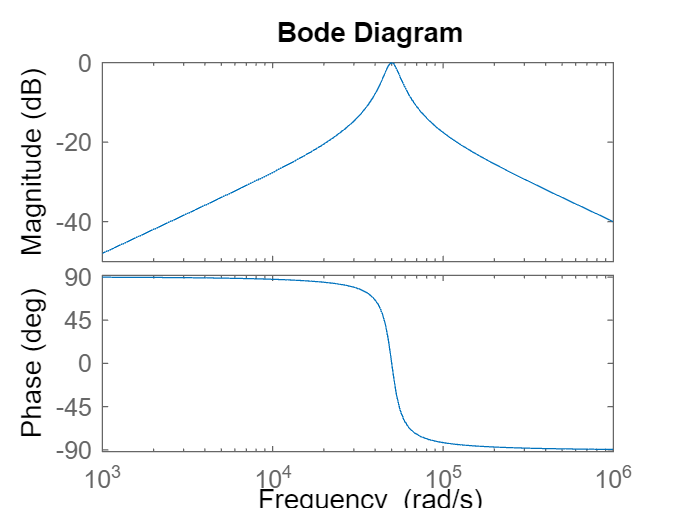


sys=tf(num,den);

bode(sys)

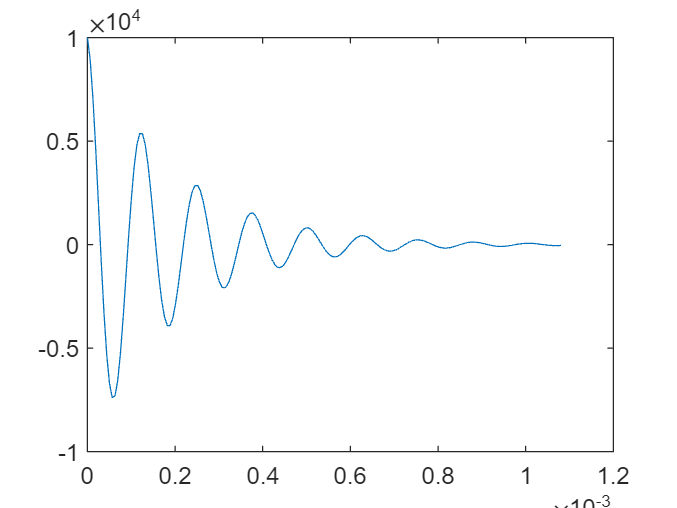


[y,tOut] = impulse(sys);
plot(tOut,y)

resonant angular frequency

w0=1/sqrt(L*C)

w0 = 5.0000e+04

fs=2*10^6/2*pi

fs = 3.1416e+06

The calculated angular frequency is consistent with bode plot

To **capture the full bandwidth of a system** as shown in a **Bode plot**, the **sampling frequency** must satisfy the **Nyquist criterion**, which states: fs≥2⋅fmax

Where:

- fmax is the **maximum frequency of interest** (i.e. the highest frequency shown or relevant in the Bode plot),

- fs is the **sampling frequency**.

In practice it is recommended to use a sampling rate 2-5 x higer than fmax

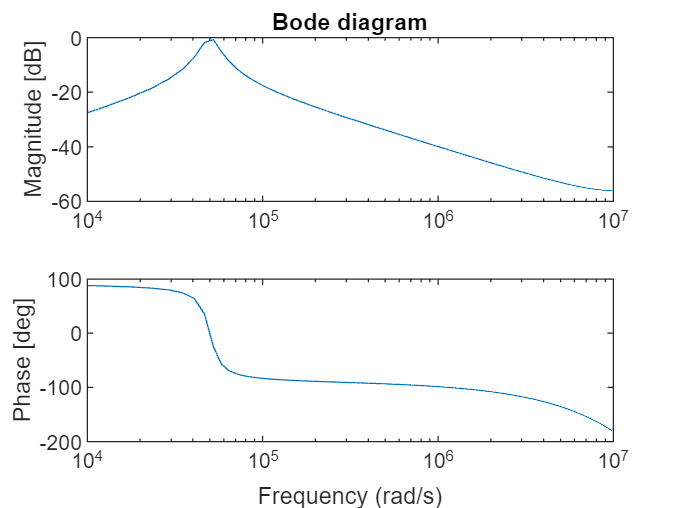

dt=1/fs;
% out=sim("Lab5sim");
% save out out
load out 
x1=out.x1.Data;
y1=out.y1.Data;
N=length(x1);
X=fft(x1);
Y=fft(y1);
H=Y./X;
H_mag=abs(H);
df=fs/N;
f=(0:df:fs-1);
figure
title('Bode diagram')
subplot(211)
semilogx(f(1:floor(N/2))*2*pi,20*log10(H_mag(1:floor(N/2))))
title('Bode diagram')

xlim([10e3,10e6]);
ylabel('Magnitude [dB]')
subplot(212)
H_phase=angle(H);
semilogx(f(1:floor(N/2))*2*pi,rad2deg(H_phase(1:floor(N/2))))
xlim([10e3,10e6]);

ylabel('Phase [deg]')
xlabel('Frequency (rad/s)')